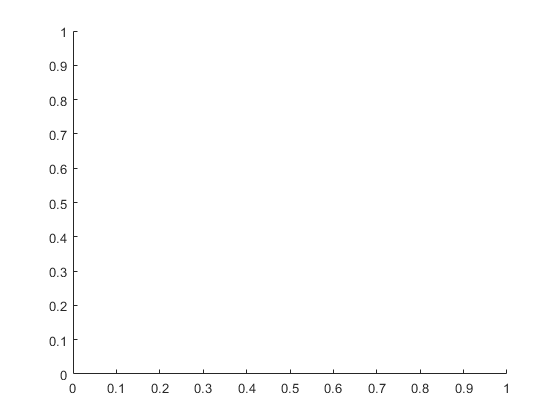

warning('off', 'MATLAB:polyfit:RepeatedPointsOrRescale');
addpath('./wave_matlab/'); % for wavelet analysis
addpath('./dnsfnu/'); % for plot coordinates
addpath('./acf/'); % for autocorrelation function
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                           User defined variables                       %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dataDirectory = 'E:\MATLAB Drive\Eclipse\gravity-wave-analysis\Profile\Profile\';
saveDirectory = 'E:\MATLAB Drive\Eclipse\gravity-wave-analysis\Profile\';
% The w/f happened with no correction to wind direction, a window of
% 12km - 40km, and a heightSamplingFrequency of 5m.
% heightSamplingFrequency of 7m makes a 90 w/f show up.
showPowerSurfaces = true; % Do you want to show the wavelet transform power surfaces?
save = true; % Do you want to save the data? It will save in saveDirectory.
lowerCutOffAltitude = 12000; % Altitude where you want to start analysis
upperCutOffAltitude = 40000; % Altitude where you want to end analysis - 
% a value of 40000 will go to the highest point in the profile.
latitude = 45; % Latitude of launch location.
heightSamplingFrequency = 5;
printData = true;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                            End of user editing                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
textFiles = fullfile(dataDirectory, "*.txt");
files = dir(textFiles);
f1 = figure;
f2 = figure;
set(0, 'CurrentFigure', f1);
hold on;

set(0, 'CurrentFigure', f2);
hold on;

counter = 0;
first = true;
minLat = Inf;
minLon = Inf;
maxLat = -Inf;
maxLon = -Inf;
% Iterate over files in dataDirectory
for i=1:size(files)
    current = files(i).name;
    fprintf("Current file: %s\n", current);
    current = fullfile(dataDirectory, current);
    try
        % All analysis logic is in doAnalysis
        [latitudeArray, longitudeArray, altitude, data, ~, ~, ~, ~] = doAnalysis(current, ...
            save, saveDirectory, showPowerSurfaces, lowerCutOffAltitude, upperCutOffAltitude,...
            latitude, heightSamplingFrequency, printData);
        altitude = seconds(altitude);
        % the rest of the code here is plotting and error checking.
        if isempty(data)
            continue;
        end
        % Get latitude of bounding box around all radiosondes
        mLat = min(latitudeArray);
        mLon = min(longitudeArray);
        mxLat = max(latitudeArray);
        mxLon = max(longitudeArray);
        if mxLon > maxLon
            maxLon = mxLon;
        end
        if mxLat > maxLat
            maxLat = mxLat;
        end
        if mLat < minLat
            minLat = mLat;
        end
        if mLon < minLon
            minLon = mLon;
        end
        % plot the latitude, longitude, and altitude in 3d
        set(0, 'CurrentFigure', f1);
        plot3(longitudeArray, latitudeArray, altitude);
        % 3D plot magnitudes of quiver have to be 0 or else the plot is 
        % weirdly scaled. The 3D plot is just for altitude of detection and
        % propagation direction.
        magnitudes = 0*data.axial_ratio + 0.1;
        angle = data.propagation_dir;
        quiver3(data.lon_of_detection, data.lat_of_detection, ...
            data.alt_of_detection_km*1000, magnitudes.*cosd(angle), ...
            magnitudes.*sind(angle), zeros(size(angle), 'like', angle), 0);
        set(0, 'CurrentFigure', f2);
        offset = 10;
        % Plot a vertical line with placeholder, each one offset by 10 from
        % each other on the x-axis.
        altitude = seconds(altitude);
        placeholder = zeros(size(altitude), 'like', altitude) + (counter*offset);
        plot(placeholder, altitude/1000, 'k'); % plot altitude in km.
        hold on;
        xlim([-15, 160]);
        ylim([9, 60]);
        magnitudes = data.axial_ratio;
        % The magnitudes of the red lines are the axial ratios of the
        % gravity waves - axial ratio = intrinsic frequency / coriolis
        % frequency.
        % The for loop below just plots the red lines in the direction of
        % propagation of the gravity wave
        for q=1:size(data.alt_of_detection_km)
            x1 = counter*offset;
            x2 = counter*offset + magnitudes(q)*cosd(angle(q));
            y1 = data.alt_of_detection_km(q);
            y2 = data.alt_of_detection_km(q) + magnitudes(q)*sind(angle(q));
            [xf, yf] = ds2nfu([x1 x2], [y1 y2]);
            annotation(gcf, 'arrow', xf,yf, 'color', '#9a0200', 'LineWidth', 2)
            %plot([x1 x2], [y1 y2], 'color', '#9a0200', 'linewidth', 3);
        end
        scaleFactor = 15;
        if first
            indicesForFilenames = i;
            offsets = counter*offset;
            first = false;
        else
            indicesForFilenames = cat(2, indicesForFilenames, i);
            offsets = cat(2, offsets, counter*offset);
        end
        counter = counter + 1;
    catch e
        if (strcmp(e.identifier, 'MATLAB:table:UnrecognizedVarName'))
            fprintf("Data file %s does not contain a variable needed for analysis. Rerun sounding.\n", files(i).name);
            fprintf("----------------------------\n");
            continue;
        end
        rethrow(e);
    end
        fprintf("----------------------------\n");
end

Current file: C10_041713_070219_MREDI.txt


Check for missing argument or incorrect argument data type in call to function 'doAnalysis'.

set(0, 'CurrentFigure', f1);
% xlim([minLon maxLon])
% ylim([minLat maxLat])
xlabel('Longitude (deg)');
ylabel("Latitude (deg)");
zlabel("Altitude (m)");
title("Gravity wave detection altitudes and directions (deg cw from North)");
set(0, 'CurrentFigure', f2);
allFiles = dir(textFiles);
filenames = allFiles(indicesForFilenames)';

for i=1:size(filenames, 2)
   filenames(i).name = filenames(i).name(1:3);
   filenames(i).name(1) = 'F';
end

xticks(offsets);
yticks([0 10 20 30])
xticklabels(["0", "10", "20", "30"]) 
xticklabels({filenames.name});
set(gca,'XTickLabelRotation', 45, 'fontsize', 16)
ylabel("Altitude of detection (km)")
xlabel("Flight number")
title("Propagation direction and detection altitude of gravity waves", 'fontsize', 16);